Computation of Transfer function for Lateral Acceleration Gain

z= iddata(out.lat_acc_var.Data, out.steer_inp_var.Data, 0.001)

z =

Time domain data set with 17376 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


sys = tfest(z, 2, 2);

num = sys.Numerator

num =     1.4841   17.8156  164.1202


den = sys.Denominator

den =     1.0000   16.4405  112.6463


G = tf(num, den)

G =
 
  1.484 s^2 + 17.82 s + 164.1
  ---------------------------
     s^2 + 16.44 s + 112.6
 
Continuous-time transfer function.
Model Properties


Computation of Transfer function for Yaw rate

yaw_rate_tf_var = iddata(out.yaw_rate_var.Data, out.steer_inp_var.Data, 0.001)

yaw_rate_tf_var =

Time domain data set with 17376 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


yaw_rate_tf = tfest(yaw_rate_tf_var, 2, 1);

num_yr = yaw_rate_tf.Numerator

num_yr =     1.0792   18.6541


den_yr = yaw_rate_tf.Denominator

den_yr =     1.0000   26.6830  211.4759



TF = tf(num_yr, den_yr)

TF =
 
     1.079 s + 18.65
  ---------------------
  s^2 + 26.68 s + 211.5
 
Continuous-time transfer function.
Model Properties


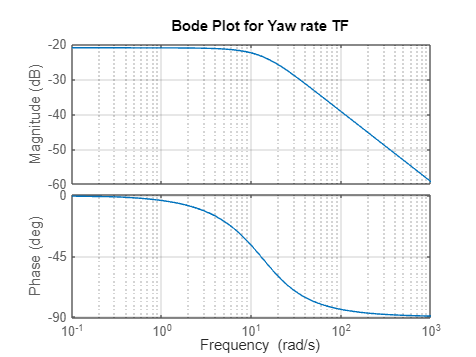


% Plot the Bode plot
figure;
bode(TF);
grid on;
title('Bode Plot for Yaw rate TF');

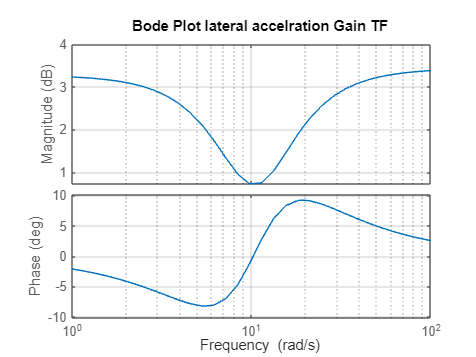

figure;
bode(G);
grid on;
title('Bode Plot lateral accelration Gain TF');